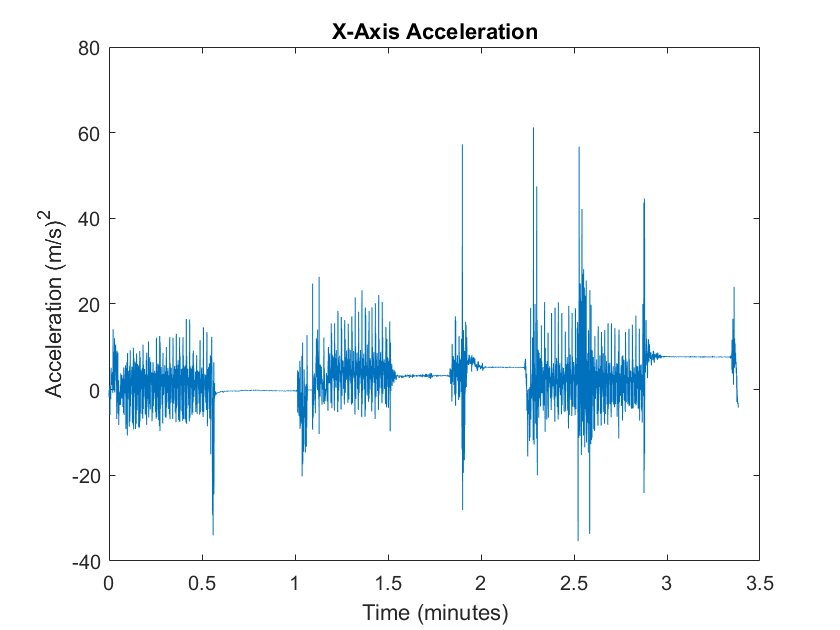

load('vigorousPlusThreeFalls.mat');
x=Acceleration.X; %(m/s)^2 Acceleration
y=Acceleration.Y; %(m/s)^2 Acceleration
z=Acceleration.Z; %(m/s)^2 Acceleration

skip=1; %(s) Ensures no redetection of the same fall
start_downtime=1.5; %(s) Time it takes to fall and begins time frame after the fall (s)
end_downtime=3; %(s) End of the time frame for after
low_bound=0; %(Hz) Frequency lower bound
high_bound=2; %(Hz) Frequency upper bound
threshold=700; %(Magnitude FFT) Summed magnitude of the FFT for specified frequency range
down_threshold=1000; %(Magnitude FFT) Summed magnitude of the FFT for specified frequency range and time to determine downtime after fall

fs=100; %(Hz) Frequency
t=[0:1/fs:((length(x)-1)/fs)]'; %Creates the right time signatures
plot(t/60,x)
title('X-Axis Acceleration')
xlabel('Time (minutes)')
ylabel('Acceleration (m/s)^2')

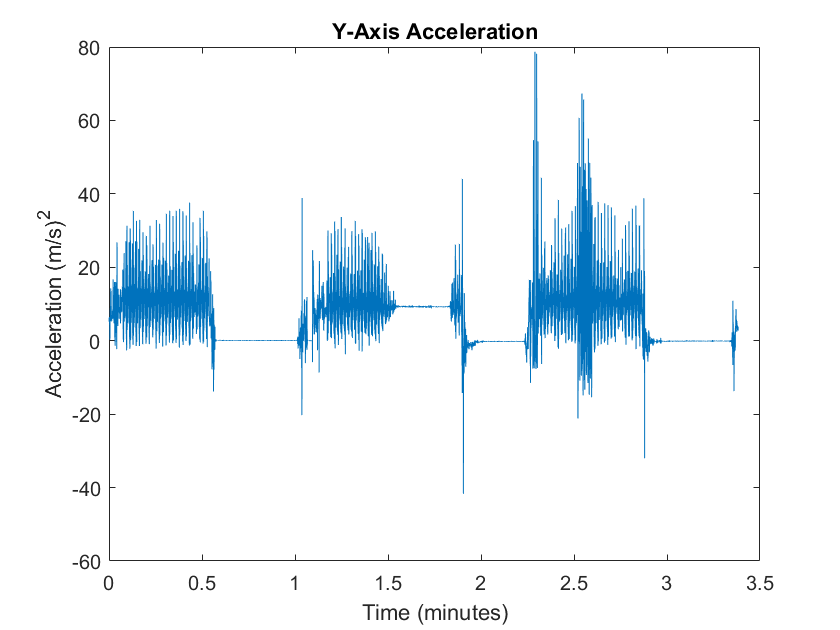

plot(t/60,y)
title('Y-Axis Acceleration')
xlabel('Time (minutes)')
ylabel('Acceleration (m/s)^2')

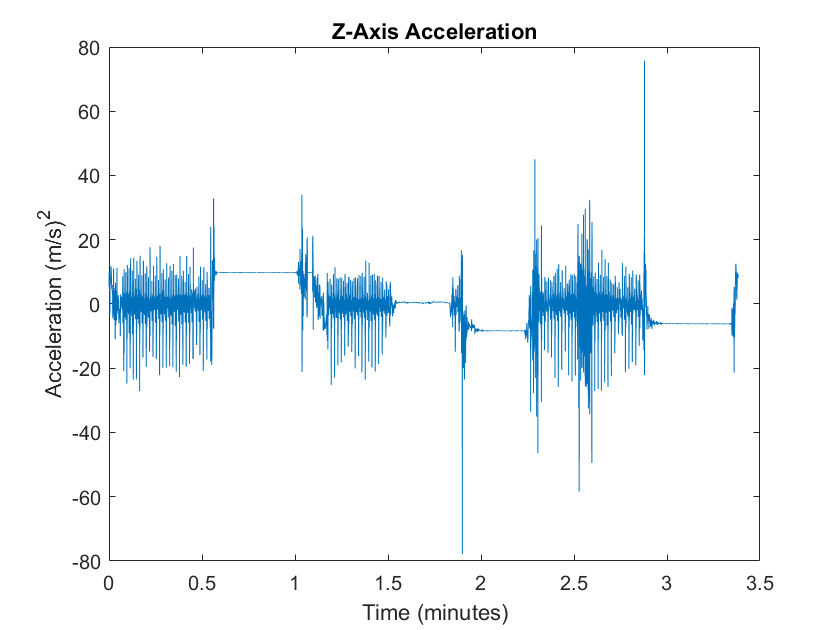

plot(t/60,z)
title('Z-Axis Acceleration')
xlabel('Time (minutes)')
ylabel('Acceleration (m/s)^2')

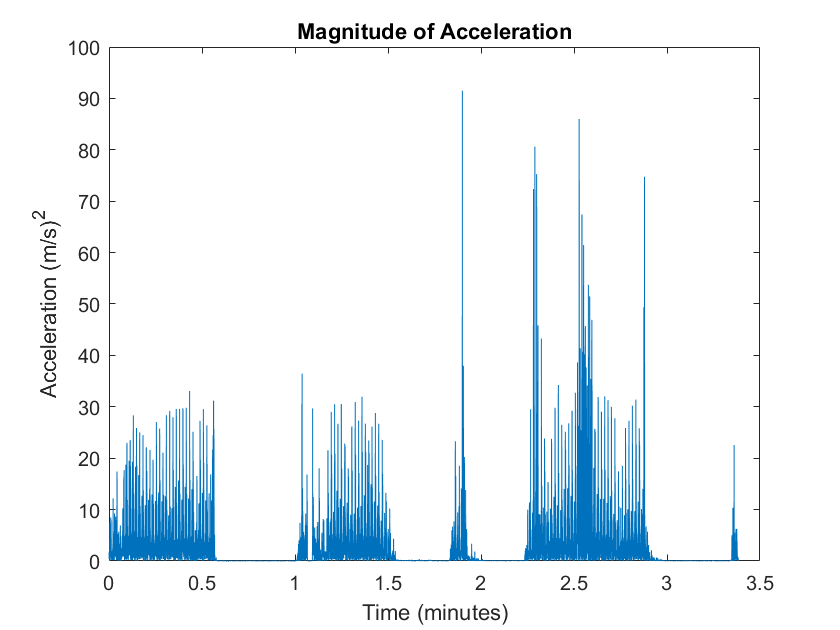


m=abs(vecnorm([x(:,1),y(:,1),z(:,1)]')-9.8); %Takes the magnitude of the 3-axis of acceleration and attempts to compensate for gravity



plot(t/60,m) %plots the magnitude of acceleration over time
title('Magnitude of Acceleration')
xlabel('Time (minutes)')
ylabel('Acceleration (m/s)^2')

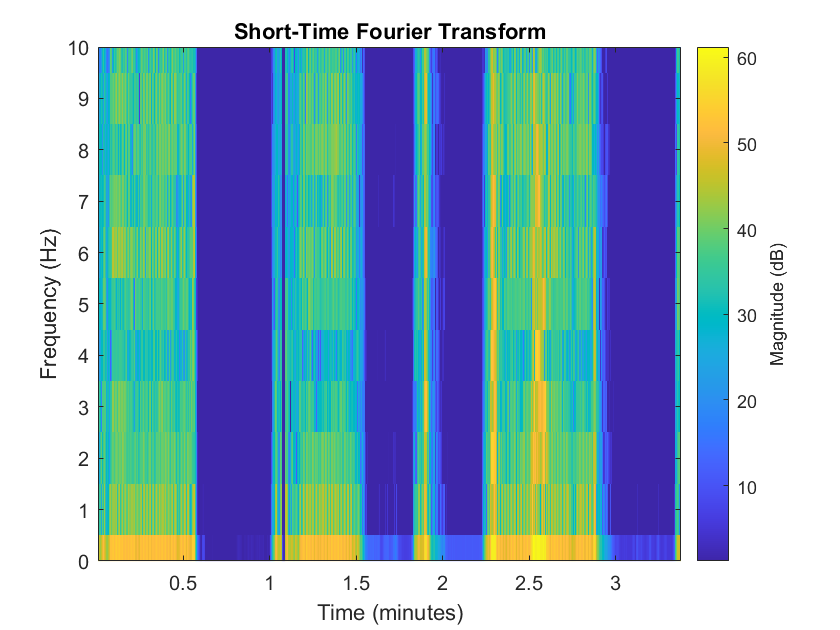



FFTLength=fs;
stft(m ,fs,'Window',kaiser(FFTLength,2),'OverlapLength',round(0.75*FFTLength),'FFTLength',FFTLength); %Takes the STFT of the magnitude for plotting
ylim([0;10]) %Frequencies of different actions are included

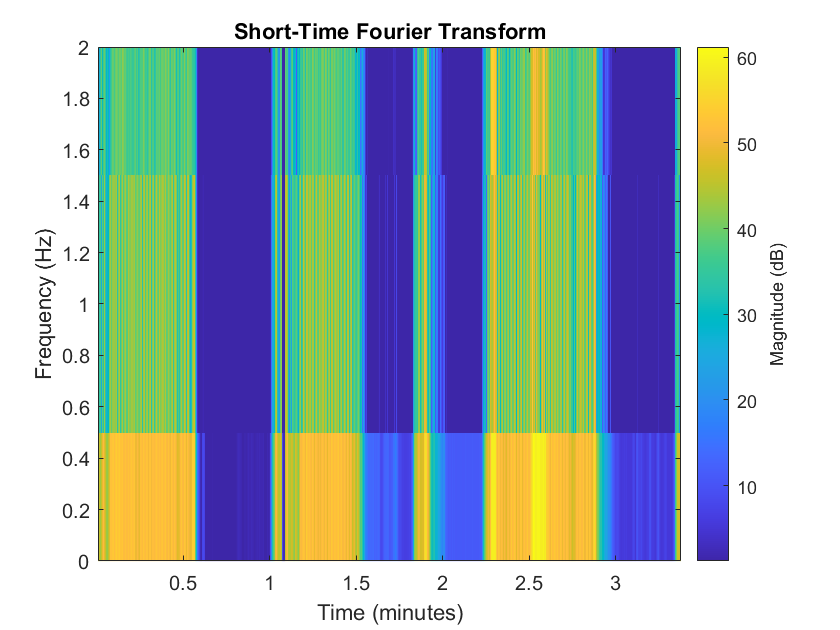


mstft1=stft(m ,fs,'Window',kaiser(FFTLength,2),'OverlapLength',round(0.75*FFTLength),'FFTLength',FFTLength); %Takes the STFT for data


stft(m ,fs,'Window',kaiser(FFTLength,2),'OverlapLength',round(0.75*FFTLength),'FFTLength',FFTLength);%Takes the STFT for plotting in a certain frequency spectrum
ylim([0;2]) %Frequency range of the fall

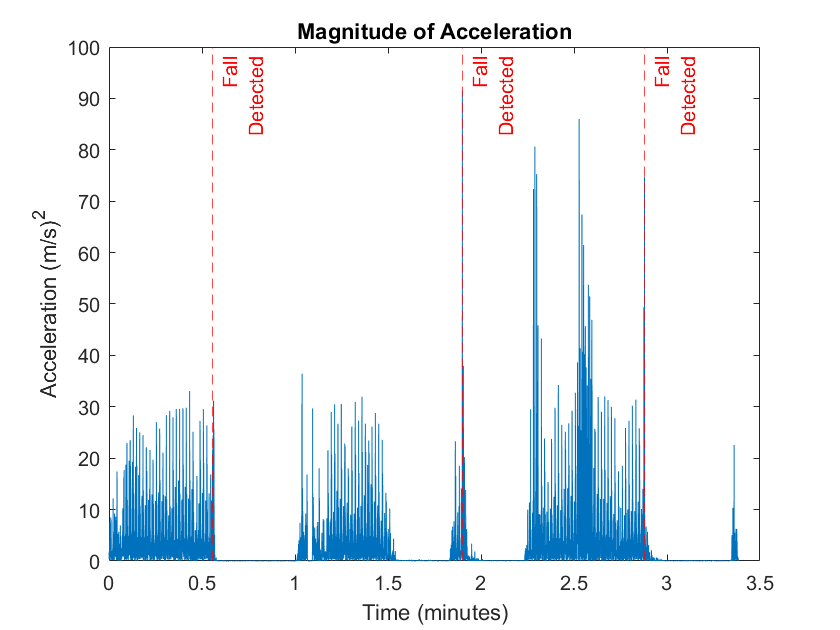



%Bound frequency
frequency_bounded_mstft=mstft1(FFTLength/2+low_bound:FFTLength/2+high_bound,:);

%Normilize, convert imaginary to real
for i =(1:length(frequency_bounded_mstft(:,1)))
    for j =(1:length(frequency_bounded_mstft(1,:)))
        frequency_bounded_mstft_real(i,j)=norm(frequency_bounded_mstft(i,j));
    end
end

%sum frequencies in each time band
%the highest sum indicates the spectrum with the highest amplitudes -- most
%likely to occur at a fall
for k =(1:length(frequency_bounded_mstft_real(1,:)))
    sum_frequency_bounded_mstft_real(1,k)=sum(frequency_bounded_mstft_real(:,k));
end
skip=round(fs*length(mstft1(1,:))*skip/length(m(1,:)));% Converts to different timestamping

start_downtime=round(fs*length(mstft1(1,:))*start_downtime/length(m(1,:))); % Converts to different timestamping
end_downtime=round(fs*length(mstft1(1,:))*end_downtime/length(m(1,:)));% Converts to different timestamping
possible_fall=[];
w=1;
while w <length( sum_frequency_bounded_mstft_real(1,:))
    if w+end_downtime>length( sum_frequency_bounded_mstft_real(1,:)) %Exit if the index that is being iterated upon is exceeded
        break
    end
    if sum_frequency_bounded_mstft_real(1,w)>threshold %If in the sum of specified band of frequencies exeeds a threshold
        if sum(sum_frequency_bounded_mstft_real(1,w+start_downtime:w+end_downtime))<down_threshold % If after
        possible_fall=[possible_fall,w/length(sum_frequency_bounded_mstft_real(1,:))*length(m(1,:))/fs];
        w=w+skip;
        end
    end
    w=w+1;
end


plot(t/60,m)
if length(possible_fall)>0
for e=(1:length( possible_fall(1,:)))
    xline(possible_fall(1,e)/60,'--r',{'Fall','Detected'})
end
end
title('Magnitude of Acceleration')
xlabel('Time (minutes)')
ylabel('Acceleration (m/s)^2')